# Efficiency Map of Motor Drive Unit

Copyright 2021 The MathWorks, Inc.

This script collects block parameters from Motor Drive Unit block and plots the motor efficiency contour map. Make sure you have selected the block in Simulink canvas before running this script.

% Get parameter values from the block.
% Make sure you have selected the motor block before running this script.
info = MotorDriveUnitBasic_get_block_info(gcbh)

info = struct with fields:
    response_time_const_s: 0.0200
               trq_max_Nm: 163
              spd_max_rpm: 17000
             power_max_kW: 53
       efficiency_percent: 98
            speed_eff_rpm: 2000
            torque_eff_Nm: 50
    iron_to_nominal_ratio: 0.1000
        elec_loss_const_W: 30
    k_damp_Nm_per_radPerS: 0.0050
            J_rotor_kg_m2: 1.0000e-03


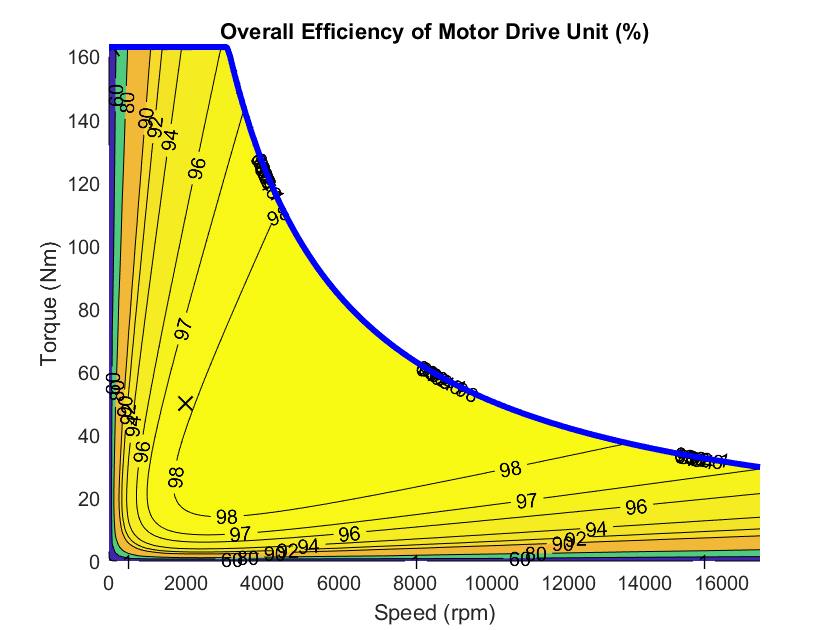

MotorDriveUnitBasic_plot_efficiency( ...
  "trq_max_Nm", info.trq_max_Nm, ...
  "spd_max_rpm", info.spd_max_rpm, ...
  "power_max_kW", info.power_max_kW, ...
  "efficiency_pct", info.efficiency_percent, ...
  "spd_eff_rpm", info.speed_eff_rpm, ...
  "trq_eff_Nm", info.torque_eff_Nm, ...
  "iron_to_nominal_ratio", info.iron_to_nominal_ratio, ...
  "elec_loss_const_W", info.elec_loss_const_W, ...
  "k_damp_Nm_per_radPerS", info.k_damp_Nm_per_radPerS, ...
  "contour_levels_pct", [1 60 80 90 92 94 96 97 98 99], ...
  "divs", 200 );